# Cart pendulum controller design

clear
close all
clc

## Select Operating Conditions

Values of y>0 lead to an inverted pendulum, and y<0 to a hanging pendulum

% operating conditions
y = [-1, 1];

## Setup model

We will initialize parameters and the linearization interface:

% initialize pendulum
init_pendulum;

% create model linearie
load("data\plant_linio.mat");
sllin = slLinearizer(mdl, io);

% select operating point
oppoints = get_oppoints(mdl, y=y);
sllin.OperatingPoints = oppoints;

## Show Open Loop Behavior

We will characterize the open loop behavior by displaying the pole zero maps for the angle and position outputs

u_L_sys = sllin.getIOTransfer({'fx'}, {'x', 'x_dot', 'theta', 'theta_dot'});
u_L_sys.InputName = {'f_x'};
u_L_sys.OutputName = {'x', 'x_{dot}', '\theta', '\tetha_{dot}'};
u_L_sys = ss_x_change(u_L_sys, [3,4,1,2]); % reorder so that C is the identity


### Inverted pendulum

The inverted pendulum is characterized by the inverted pendulum unstable poles and a RHP zero in position, which prevents position feedback from being used to stabilize the pendulum.

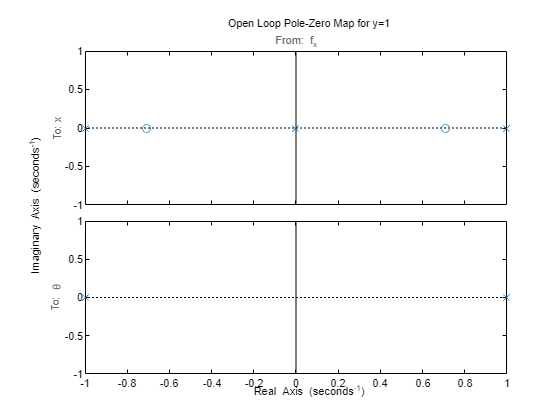

indices = find(y>0);
for i=1:length(indices)
    idx=indices(i);
    figure()
    h = iopzplot(u_L_sys([1,3],:,idx), default_pzoptions);
    p = h.getoptions;
    p.Title.String = "Open Loop " + p.Title.String + " for y=" + y(idx);
    h.setoptions(p);
end

### Hanging pendulum

The hanging pendulum is characterized by the oscillatory pole-zeros. The zeros are quite close to the zeros with a smaller magnitude, which implies position feedback allows only a small effect on angle stabilization.

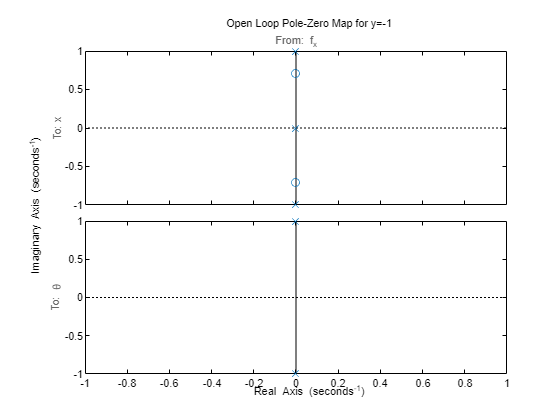

indices = find(y<0);
for i=1:length(indices)
    idx=indices(i);
    figure()
    h = iopzplot(u_L_sys([1,3],:,idx), default_pzoptions);
    p = h.getoptions;
    p.Title.String = "Open Loop " + p.Title.String + " for y=" + y(idx);
    h.setoptions(p);
end

## Close the loop using an LQR controller

We will close the loop using an LQR controller here. We will take as a constraint that the system is limited to a maximum input magnitude of 1.

For the inverted pendulum it suffices to add some state gain in position. The angle is unstable so the LQR will stabilize with Q=0 using a minimum control input (which will simply mirror the RHP poles into the LHP). The position needs some gains to move the position poles at the origin to the left.

The hanging pendulum needs some extra gain in the angle as well since the natural gains are in the imaginary axis and closing the position loop only will not provide enough damping. 

% compute gains
for i=length(y):-1:1
    if y(i)>0
        q = [1,1,0,0]; % for an inverted pendulum it is enough to stabilize it (need not be zero because we have poles at the origin)
    else
        q = [1,0,10,0]; % for a handing pendulum we need to prevent excessive oscillation
    end
    k_lqr(:,:,i) = lqr(u_L_sys(:,:,i), diag(q), 1);
    k_lqr(:,:,i) = k_lqr(:,:,i)/u_L_sys(:,:,i).C;
end

% assemble closed loop system
lqr_T_sys = feedback([u_L_sys;1] * k_lqr, eye(4,5)) * [1;0;0;0];
lqr_T_sys.InputName = {'x_{ref}'};
lqr_T_sys.OutputName = [u_L_sys.OutputName; {'u'}];


We show the resulting system by displaying the pole zero maps and the step plots.

### Inverted Pendulum

For the inverted pendulum we can see the poles are well damped. The final system still contains the RHP zero on position which is the main limitation in system performance.

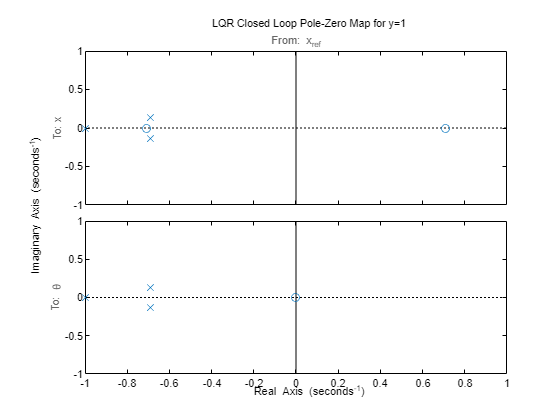

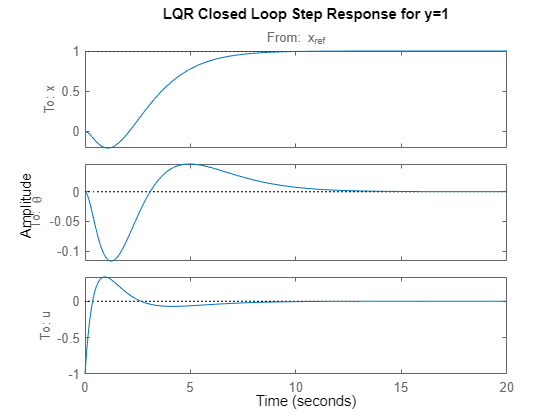

% select inverted pendulum systems
indices = find(y>0);
for i=1:length(indices)
    idx=indices(i);
    % IO Plot
    figure();
    h = iopzplot(lqr_T_sys([1,3],:,idx), default_pzoptions);
    p = h.getoptions;
    p.Title.String = "LQR Closed Loop " + p.Title.String + " for y=" + y(idx);
    h.setoptions(p);

    % Step plot
    figure();
    h = stepplot(lqr_T_sys([1,3,5],:,idx), 20);
    p = h.getoptions;
    p.Title.String = "LQR Closed Loop " + p.Title.String + " for y=" + y(idx);
    h.setoptions(p);
end

### Hanging Pendulum

We can see in this case the system has less damping, the position poles have not moved significantly to the left, but we've already hit the input limit. At this point it would be a matter of trying different weights for the LQR synthetization, probably adding weight to velocity.

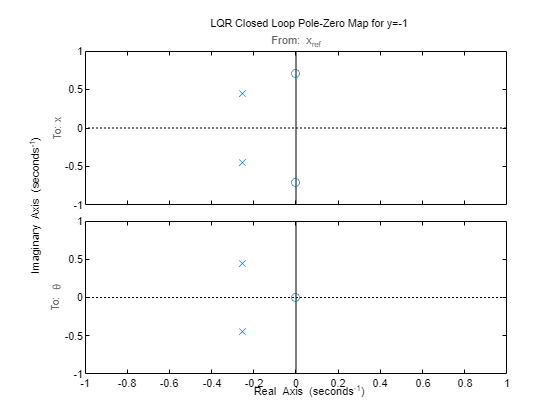

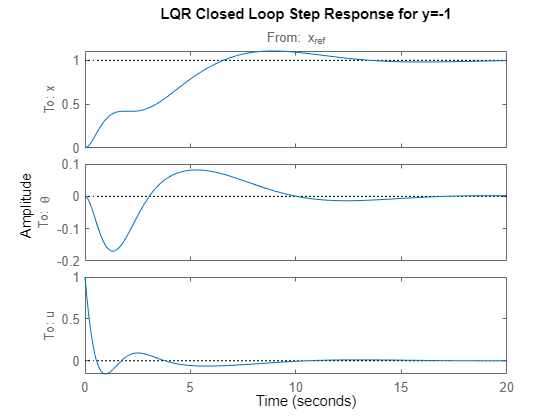

% select hanging pendulum systems
indices = find(y<0);
for i=1:length(indices)
    idx=indices(i);
    % IO PZ Plot
    figure();
    h = iopzplot(lqr_T_sys([1,3],:,idx), default_pzoptions);
    p = h.getoptions;
    p.Title.String = "LQR Closed Loop " + p.Title.String + " for y=" + y(idx);
    h.setoptions(p);

    % Step plot
    figure();
    h = stepplot(lqr_T_sys([1,3,5],:,idx), 20);
    p = h.getoptions;
    p.Title.String = "LQR Closed Loop " + p.Title.String + " for y=" + y(idx);
    h.setoptions(p);
end

## Close the loop the good ol' way

Here we will close the loop using Root Locus techniques. I've never closed the cart pendulum this way, but it is interesting since it forces you to consider the physics.

We will do it by closing first an inner loop on theta and then an outer on position.

% angle controller
k_theta_pd = @(kp, td) kp*[0, 0, 1, td]; % PD controller signature
k_theta_rl = NaN(1,4,length(y));

% position controller
k_x_pd = @(kp, td) kp*[1, td, 0, 0]; % PD controller signature
k_x_rl = NaN(1,4,length(y));

### Inverted pendulum

indices = find(y>0);

#### Inner Loop: Angle Closure

We show the root locus for the inner loop. By using theta and theta dot feedback we are using a PD controller, where the D term places a zero, and the P term controls the root locus closure.

The location of the zero is chosen such that is placed on top on the LHP zero in position. This way the unstable pole will move close to the position LHP zero and stay out of the influence of the RHP zero.

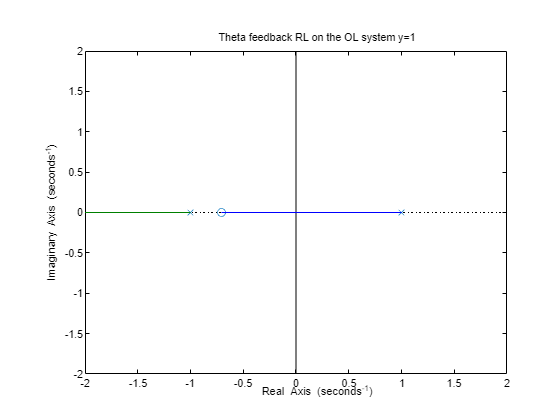

for i=1:length(indices)
    idx=indices(i);
    % Selected PD gains
    s_theta_zero = 1 * abs(min(real(zero(u_L_sys(1,:,idx)))));  % selected zero
    k_theta_rl(:,:,idx) = k_theta_pd(12,1/s_theta_zero);          % selected gain

    % Root locus plot
    theta_ol_sys(:,:,idx) = k_theta_pd(1,1/s_theta_zero)*u_L_sys(:,:,idx); %#ok<SAGROW> % with unity gain in P
    figure();
    h = rlocusplot(theta_ol_sys(:,:,idx), default_pzoptions(zoom=2));
    p = h.getoptions;
    p.Title.String = "Theta feedback RL on the OL system y="+y(idx);
    h.setoptions(p);
end

Note: this is my first time using livescripts "seriously", when using the control plots, some of the properties are lost. If you want to keep the information, you can create the figure with:

% figure('Visible', 'on');

#### Outer Loop: Position Closure

The closure of the outer loop has a few interesting things:

- The feedback uses negative gain, thus leading to an unsual Root Lous plot (see [Ogata -  RL for Positive feedback systems](https://www.benardmakaa.com/wp-content/uploads/2018/05/Root-Locus-Plots-of-Positive-Feedback-Systems-Ongata.pdf))

- The poles in the origin move left and met beyond the stabilized pole of the pendulum and the position RHP zero

- However, as the gain increases the angle poles move to the RHP zero, but also this what moves the position poles left, leading to competing objectives

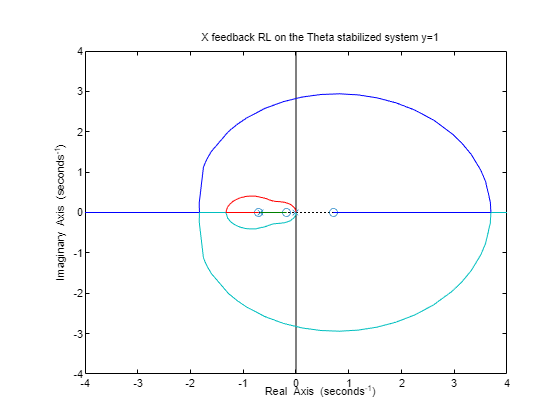

for i=1:length(indices)
    idx=indices(i);
    % Close the inner to support the outer
    rl_theta_T_sys(:,:,idx) = feedback(u_L_sys(:,:,idx), k_theta_rl(:,:,idx)); %#ok<SAGROW> 
    rl_theta_T_sys.InputName = {'u'};
    rl_theta_T_sys.OutputName = u_L_sys.OutputName;

    % Selected PD gains
    s_x_zero = 1/4*max(real(zero(rl_theta_T_sys(1,:,idx))));    % selected zero
    k_x_rl(:,:,idx) = k_x_pd(-1,1/s_x_zero);                    % selected gain

    % Root locus plot
    x_ol_sys(:,:,idx) = k_x_pd(-1,1/s_x_zero)*rl_theta_T_sys(:,:,idx); %#ok<SAGROW>  % with unity gain in P
    figure();
    h = rlocusplot(x_ol_sys(:,:,idx), default_pzoptions(zoom=4));
    p = h.getoptions;
    p.Title.String = "X feedback RL on the Theta stabilized system y="+y(idx);
    h.setoptions(p);
end

#### Closed Loop: Combine both

After combining both loop closures

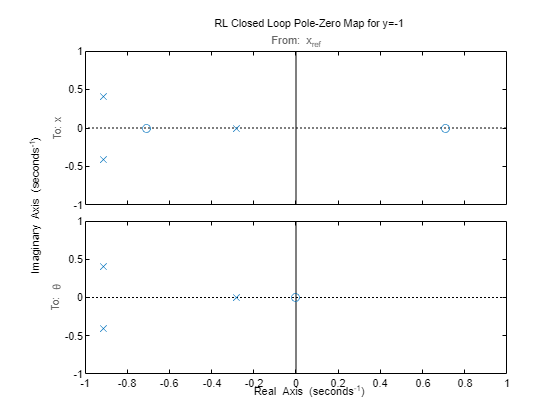

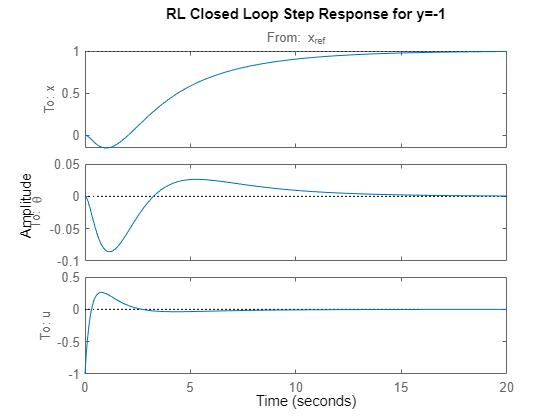

% close the loop: all
k_rl = k_theta_rl+k_x_rl;
rl_T_sys = feedback([u_L_sys;1] * k_rl, eye(4,5)) * [1;0;0;0];
rl_T_sys.InputName = {'x_{ref}'};
rl_T_sys.OutputName = [u_L_sys.OutputName; {'u'}];

for i=1:length(indices)
    idx=indices(i);
    % IO PZ Plot
    figure();
    h = iopzplot(rl_T_sys([1,3],:,idx), default_pzoptions);
    p = h.getoptions;
    p.Title.String = "RL Closed Loop " + p.Title.String + " for y=" + y(i);
    h.setoptions(p);

    % Step plot
    figure();
    h = stepplot(rl_T_sys([1,3,5],:,idx), 20);
    p = h.getoptions;
    p.Title.String = "RL Closed Loop " + p.Title.String + " for y=" + y(i);
    h.setoptions(p);
end

### Hanging pendulum

indices = find(y<0);

#### Inner Loop: Angle Closure

We will place the zero as an attractor in the LHP plane at 1/3 the oscillating frequency

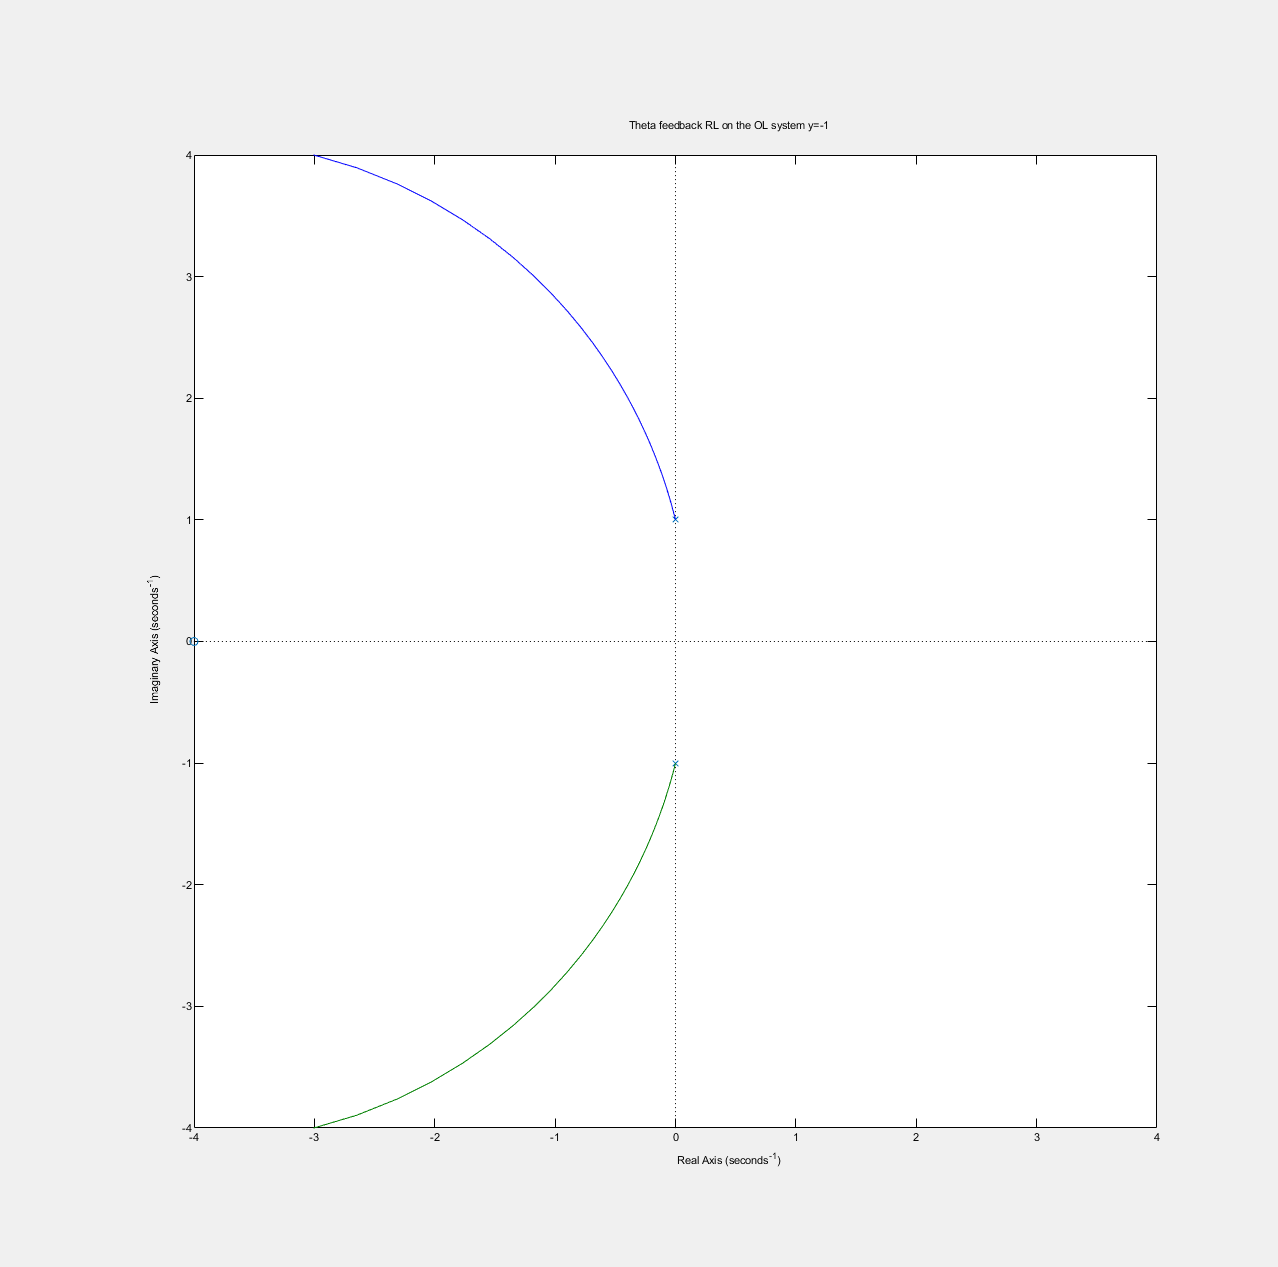

for i=1:length(indices)
    idx=indices(i);
    % Selected PD gains
    s_theta_zero = 4 * max(abs(pole(u_L_sys(:,:,i))));  % selected zero
    k_theta_rl(:,:,idx) = k_theta_pd(-3,1/s_theta_zero);   % selected gain

    % Root locus plot
    theta_ol_sys(:,:,idx) = k_theta_pd(-1,1/s_theta_zero)*u_L_sys(:,:,idx); % with unity gain in P
    figure();
    h = rlocusplot(theta_ol_sys(:,:,idx), default_pzoptions(zoom=4));
    p = h.getoptions;
    p.Title.String = "Theta feedback RL on the OL system y="+y(idx);
    h.setoptions(p);
end

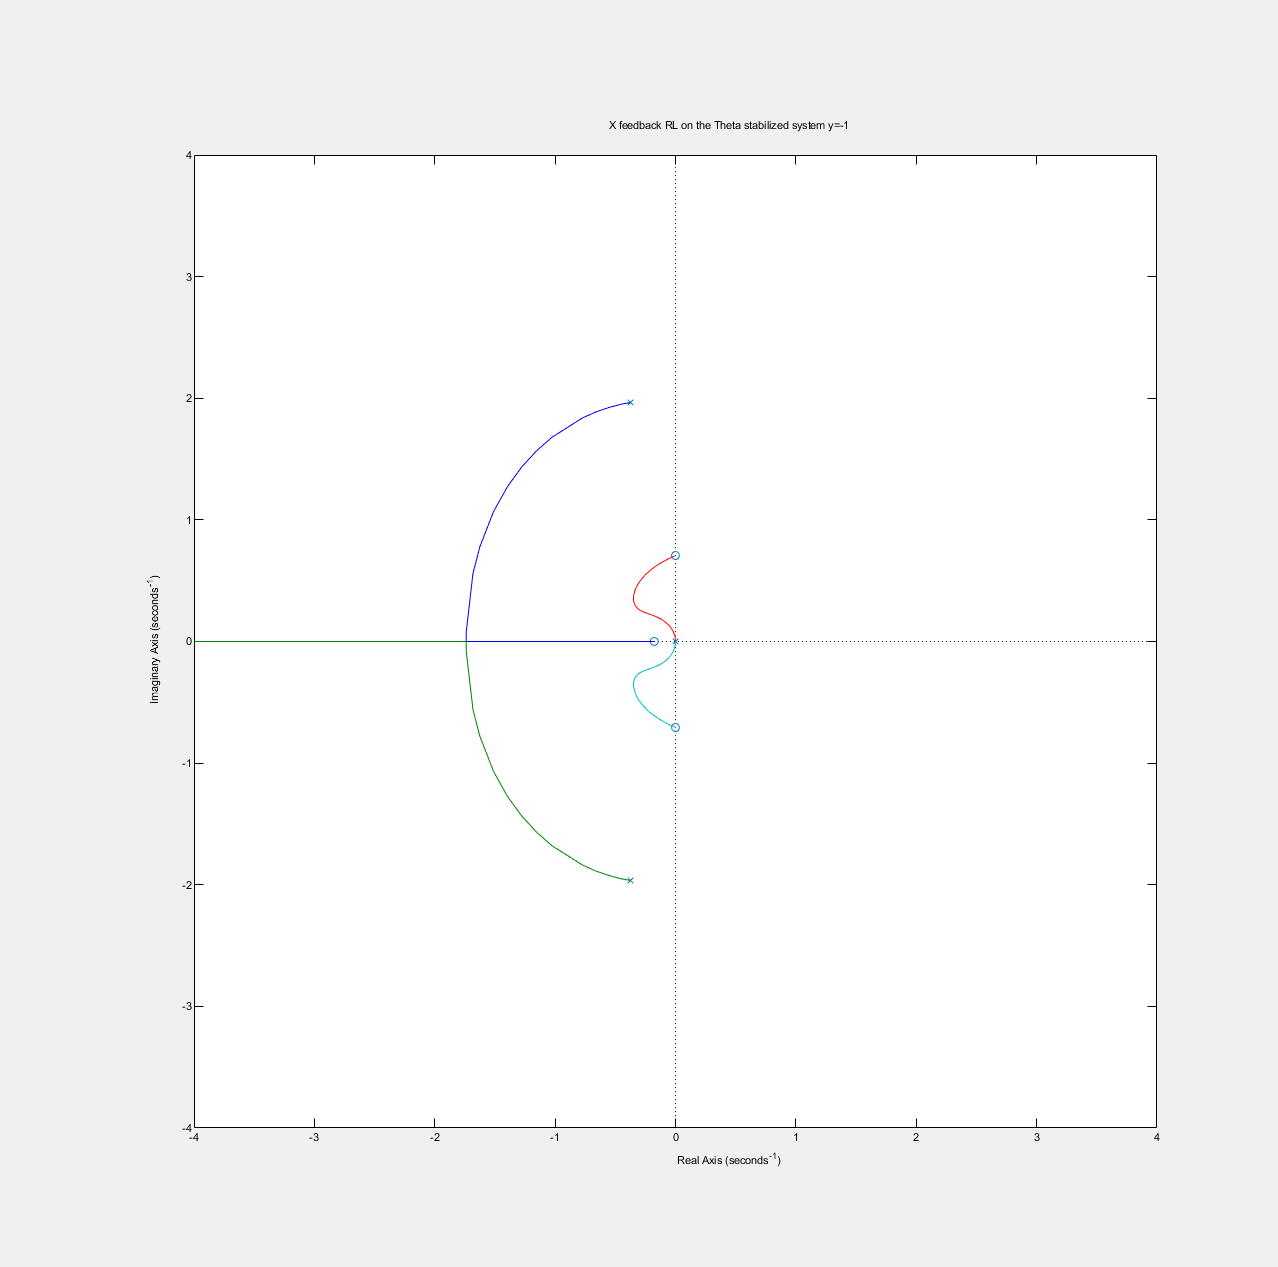

for i=1:length(indices)
    idx=indices(i);
    % Close the inner to support the outer
    rl_theta_T_sys(:,:,idx) = feedback(u_L_sys(:,:,idx), k_theta_rl(:,:,idx));
    rl_theta_T_sys.InputName = {'u'};
    rl_theta_T_sys.OutputName = u_L_sys.OutputName;

    % Selected PD gains
    s_x_zero = 1/3 * max(abs(zero(rl_theta_T_sys(1,:,idx))));  % selected zero
    k_x_rl(:,:,idx) = k_x_pd(.6,1/s_x_zero);                       % selected gain

    % Root locus plot
    x_ol_sys(:,:,idx) = k_x_pd(1,1/s_x_zero)*rl_theta_T_sys(:,:,idx); % with unity gain in P
    figure();
    h = rlocusplot(x_ol_sys(:,:,idx), default_pzoptions(zoom=4));
    p = h.getoptions;
    p.Title.String = "X feedback RL on the Theta stabilized system y="+y(idx);
    h.setoptions(p);
end

#### Closed Loop: Combine both

After combining both loop closures

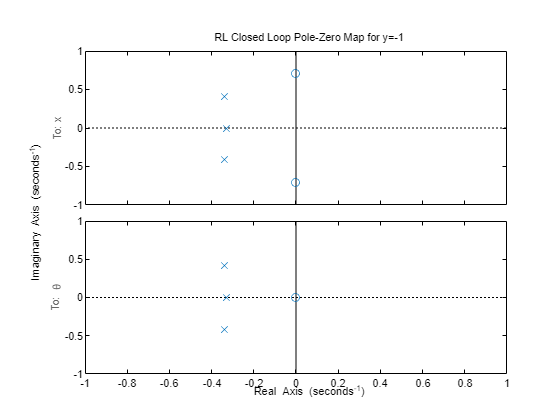

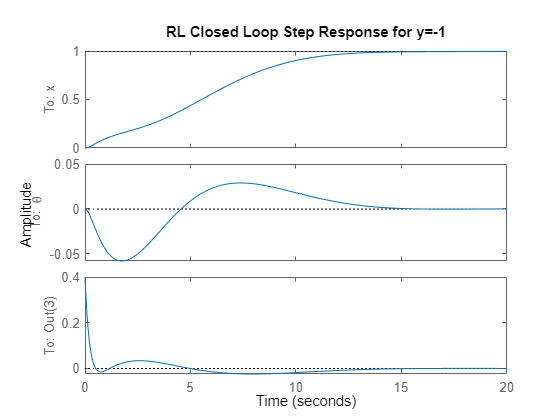

% close the loop: all
k_rl = k_theta_rl+k_x_rl;
rl_T_sys = feedback([u_L_sys;1] * k_rl, eye(4,5)) * [1;0;0;0];

for i=1:length(indices)
    idx=indices(i);
    % IO PZ Plot
    figure();
    h = iopzplot(rl_T_sys([1,3],:,idx), default_pzoptions);
    p = h.getoptions;
    p.Title.String = "RL Closed Loop " + p.Title.String + " for y=" + y(i);
    h.setoptions(p);

    % Step plot
    figure();
    h = stepplot(rl_T_sys([1,3,5],:,idx), 20);
    p = h.getoptions;
    p.Title.String = "RL Closed Loop " + p.Title.String + " for y=" + y(i);
    h.setoptions(p);
end

## Auxiliary functions

#### Standardize the pzoptions

function pzopts = default_pzoptions(options)
arguments
    options.zoom = 1;
end
pzopts = pzoptions();
pzopts.XLimMode{1} = 'manual';
pzopts.YLimMode{1} = 'manual';
pzopts.XLim{1} = [-options.zoom, options.zoom];
pzopts.YLim{1} = [-options.zoom, options.zoom];
end